# Changement de repères

## Exemple repères kite - fenêtre de vol

La matrice de passage du repère $WR$ au repère $k_0$ s'écrit : ${}^{WR}R_{k_0 }$ ou $R^{WR} _{k_0}$ 

On a ${}^{WR}R_{k_0 } = [ {}^{WR}x_{k0}\ {}^{WR}y_{k0}\ {}^{WR}z_{k0} ]$ et ${}^{WR}P = {}^{WR}R_{k_0}\ {}^{k0}P$

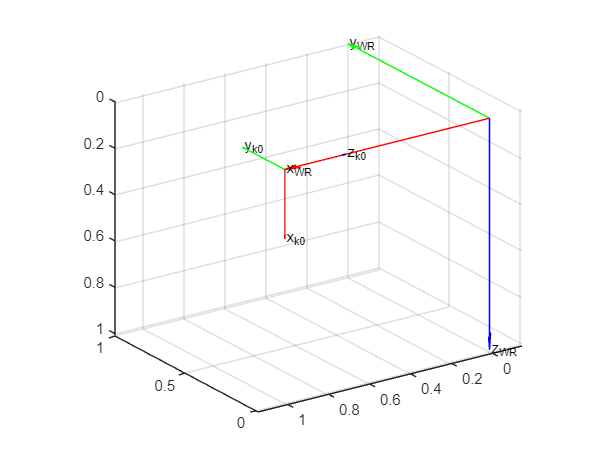

% Vecteurs unitaires du repère WR
WR_x = [1;0;0];
WR_y = [0;1;0];
WR_z = [0;0;1];

theta = 0; % degrés
phi = 0; % degrés

WR_R_k0 = [ cosd(phi)*sind(theta) -sind(phi) -cosd(phi)*cosd(theta);...
            sind(phi)*sind(theta) cosd(theta) -sind(phi)*cosd(theta);...
            cosd(theta) 0 sind(theta)];

% Vecteurs unitaires du repère k0
k0_x = [0.3;0;0];
k0_y = [0;0.3;0];
k0_z = [0;0;0.3];

% Coordonées des vecteurs x_k0, y_k0 et z_k0 dans le repères WR
WR_x_k0 = WR_R_k0*k0_x;
WR_y_k0 = WR_R_k0*k0_y;
WR_z_k0 = WR_R_k0*k0_z;

figure
hold on
ax = gca;
ax.XDir = 'Reverse';
ax.ZDir = 'Reverse';
axis equal
plot_vector([0;0;0], WR_x,"r","x_{WR}")
plot_vector([0;0;0], WR_y,"g","y_{WR}")
plot_vector([0;0;0], WR_z,"b","z_{WR}")
plot_vector([1;0;0], WR_x_k0,"r","x_{k0}")
plot_vector([1;0;0], WR_y_k0,"g","y_{k0}")
plot_vector([1;0;0], WR_z_k0,"b","z_{k0}")
grid on
rotate3d
view([-34.575 21.334])